## Q1

clear
n = 1;
k = 0;
result = 0;
while result < realmax
    k = k + 1;
    result = factorial(n);
    n = k;
end
fprintf("Largest factorial that MATLAB handles: %d\n", k - 1);

## Q2

n = 1:18;
exact_value = pi.^n;
decimals = [1 2 4 8];
errors = [];

for i = 1:4
    errorPi = abs(exact_value - round(pi,decimals(i)).^n);
    errors(end+1, :) = errorPi;
end

figure;
hold on;
title('Rounding Errors for Approximations of the Sequence π^n');
xlabel('n');
ylabel('AbsoluteError')
xlim([0 20]);
ylim([0 5]);
for i = 1:4
    plot(n,errors(i,:),'DisplayName',[num2str(decimals(i)) ' dp']);
end
legend('Location', 'best');
hold off;


## Q3

boundary = linspace(-2*pi,2*pi)
cos_fun = @(x) cos(x)

n2 = @(x) 1-x.^2./2+x.^4./24;
n4 = @(x) 1-x.^2./2+x.^4./24-x.^6./factorial(6)+x.^8./factorial(8);



plot(boundary,cos_fun(boundary),'k')
hold on
plot(boundary,n2(boundary),'r')
plot(boundary,n4(boundary),'c')
plot(boundary,maclaurin_e(8,boundary),'y')
plot(boundary,maclaurin_e(16,boundary),'m')
ylim([-1,1])
xlim([-4,4])
hold off

## Q5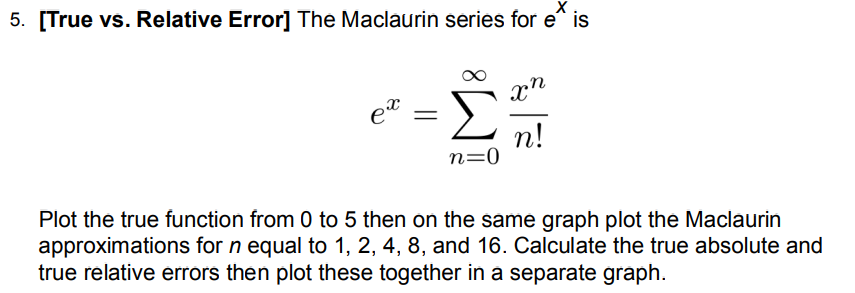

x = linspace(0, 5);
exponential = exp(x);
numbers = [1,2,4,8,16];

approx = [];

for i = 1:length(numbers)
    n = numbers(i)
    approx_values = 0;
    for j = 0:n
        approx_values = approx_values + x.^j / factorial(j)
    end
    approx(end+1, : ) = approx_values;

end

n =      1


approx_values =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


approx_values =    1.000000000000000   1.050505050505051   1.101010101010101   1.151515151515152   1.202020202020202   1.252525252525253   1.303030303030303   1.353535353535354   1.404040404040404   1.454545454545455   1.505050505050505   1.555555555555556   1.606060606060606   1.656565656565657   1.707070707070707   1.757575757575758   1.808080808080808   1.858585858585859   1.909090909090909   1.959595959595960   2.010101010101010   2.060606060606061   2.111111111111111   2.161616161616162   2.212121212121212   2.262626262626263   2.313131313131313   2.363636363636363   2.414141414141414   2.464646464646465   2.515151515151515   2.565656565656566   2.616161616161616   2.666666666666667   2.717171717171717   2.767676767676768   2.818181818181818   2.868686868686869   2.919191919191919   2.969696969696970   3.020202020202020   3.070707070707070   3.121212121212121   3.171717171717172   3.222222222222222   3.272727272727273   3.323232323232323   3.373737373737374   3.424242424242424   3

n =      2


approx_values =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


approx_values =    1.000000000000000   1.050505050505051   1.101010101010101   1.151515151515152   1.202020202020202   1.252525252525253   1.303030303030303   1.353535353535354   1.404040404040404   1.454545454545455   1.505050505050505   1.555555555555556   1.606060606060606   1.656565656565657   1.707070707070707   1.757575757575758   1.808080808080808   1.858585858585859   1.909090909090909   1.959595959595960   2.010101010101010   2.060606060606061   2.111111111111111   2.161616161616162   2.212121212121212   2.262626262626263   2.313131313131313   2.363636363636363   2.414141414141414   2.464646464646465   2.515151515151515   2.565656565656566   2.616161616161616   2.666666666666667   2.717171717171717   2.767676767676768   2.818181818181818   2.868686868686869   2.919191919191919   2.969696969696970   3.020202020202020   3.070707070707070   3.121212121212121   3.171717171717172   3.222222222222222   3.272727272727273   3.323232323232323   3.373737373737374   3.424242424242424   3

approx_values =    1.000000000000000   1.051780430568309   1.106111621263136   1.162993572084481   1.222426283032344   1.284409754106724   1.348943985307622   1.416028976635037   1.485664728088971   1.557851239669422   1.632588511376390   1.709876543209877   1.789715335169880   1.872104887256402   1.957045199469442   2.044536271808999   2.134578104275074   2.227170696867666   2.322314049586777   2.420008162432405   2.520253035404551   2.623048668503214   2.728395061728395   2.836292215080094   2.946740128558310   3.059738802163044   3.175288235894297   3.293388429752066   3.414039383736354   3.537241097847159   3.662993572084481   3.791296806448322   3.922150800938679   4.055555555555556   4.191511070298949   4.330017345168860   4.471074380165289   4.614682175288236   4.760840730537700   4.909550045913682   5.060810121416182   5.214620957045199   5.370982552800735   5.529894908682787   5.691358024691358   5.855371900826447   6.021936537088052   6.191051933476176   6.362718089990818   6

n =      4


approx_values =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


approx_values =    1.000000000000000   1.050505050505051   1.101010101010101   1.151515151515152   1.202020202020202   1.252525252525253   1.303030303030303   1.353535353535354   1.404040404040404   1.454545454545455   1.505050505050505   1.555555555555556   1.606060606060606   1.656565656565657   1.707070707070707   1.757575757575758   1.808080808080808   1.858585858585859   1.909090909090909   1.959595959595960   2.010101010101010   2.060606060606061   2.111111111111111   2.161616161616162   2.212121212121212   2.262626262626263   2.313131313131313   2.363636363636363   2.414141414141414   2.464646464646465   2.515151515151515   2.565656565656566   2.616161616161616   2.666666666666667   2.717171717171717   2.767676767676768   2.818181818181818   2.868686868686869   2.919191919191919   2.969696969696970   3.020202020202020   3.070707070707070   3.121212121212121   3.171717171717172   3.222222222222222   3.272727272727273   3.323232323232323   3.373737373737374   3.424242424242424   3

approx_values =    1.000000000000000   1.051780430568309   1.106111621263136   1.162993572084481   1.222426283032344   1.284409754106724   1.348943985307622   1.416028976635037   1.485664728088971   1.557851239669422   1.632588511376390   1.709876543209877   1.789715335169880   1.872104887256402   1.957045199469442   2.044536271808999   2.134578104275074   2.227170696867666   2.322314049586777   2.420008162432405   2.520253035404551   2.623048668503214   2.728395061728395   2.836292215080094   2.946740128558310   3.059738802163044   3.175288235894297   3.293388429752066   3.414039383736354   3.537241097847159   3.662993572084481   3.791296806448322   3.922150800938679   4.055555555555556   4.191511070298949   4.330017345168860   4.471074380165289   4.614682175288236   4.760840730537700   4.909550045913682   5.060810121416182   5.214620957045199   5.370982552800735   5.529894908682787   5.691358024691358   5.855371900826447   6.021936537088052   6.191051933476176   6.362718089990818   6

approx_values =    1.000000000000000   1.051801901613145   1.106283389621824   1.163573290295054   1.223800429901848   1.287093634711225   1.353581730992199   1.423393545013788   1.496657903045006   1.573503631354871   1.654059556212398   1.738454503886603   1.826817300646502   1.919276772761111   2.015961746499447   2.117001048130525   2.222523503923361   2.332657940146972   2.447533183070373   2.567278058962581   2.692021394092611   2.821892014729480   2.957018747142204   3.097530417599798   3.243555852371280   3.395223877725663   3.552663319931966   3.716003005259203   3.885371759976392   4.060898410352548   4.242711782656686   4.430940703157824   4.625713998124976   4.827160493827162   5.035409016533391   5.250588392512686   5.472827448034059   5.702255009366528   5.938999902779108   6.183190954540817   6.434956990920669   6.694426838187677   6.961729322610865   7.236993270459243   7.520347508001830   7.811920861507640   8.111842157245688   8.420240221484992   8.737243880494569   9

approx_values =    1.000000000000000   1.051802172712196   1.106287727206640   1.163595249318181   1.223869831258894   1.287263071618075   1.353933075362243   1.424044453835142   1.497768324757737   1.575282312228218   1.656770546721995   1.742423665091704   1.832438810567202   1.927019632755571   2.026376287641114   2.130725437585359   2.240290251327056   2.355300403982176   2.475992077043918   2.602607958382698   2.735397242246162   2.874615629259172   3.020525326423818   3.173395047119409   3.333500011102482   3.501121944506793   3.676549079843322   3.860076156000273   4.052004418243072   4.252641618214370   4.462302013934036   4.681306369799170   4.909981956584086   5.148662551440331   5.397688437896662   5.657406405859073   5.928169751610773   6.210338277812195   6.504278293500996   6.810362614092058   7.128970561377480   7.460487963526587   7.805307155085934   8.163826976979289   8.536452776507648   8.923596407349226   9.325676229559466   9.743117109571031  10.176350420193813  10

n =      8


approx_values =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


approx_values =    1.000000000000000   1.050505050505051   1.101010101010101   1.151515151515152   1.202020202020202   1.252525252525253   1.303030303030303   1.353535353535354   1.404040404040404   1.454545454545455   1.505050505050505   1.555555555555556   1.606060606060606   1.656565656565657   1.707070707070707   1.757575757575758   1.808080808080808   1.858585858585859   1.909090909090909   1.959595959595960   2.010101010101010   2.060606060606061   2.111111111111111   2.161616161616162   2.212121212121212   2.262626262626263   2.313131313131313   2.363636363636363   2.414141414141414   2.464646464646465   2.515151515151515   2.565656565656566   2.616161616161616   2.666666666666667   2.717171717171717   2.767676767676768   2.818181818181818   2.868686868686869   2.919191919191919   2.969696969696970   3.020202020202020   3.070707070707070   3.121212121212121   3.171717171717172   3.222222222222222   3.272727272727273   3.323232323232323   3.373737373737374   3.424242424242424   3

approx_values =    1.000000000000000   1.051780430568309   1.106111621263136   1.162993572084481   1.222426283032344   1.284409754106724   1.348943985307622   1.416028976635037   1.485664728088971   1.557851239669422   1.632588511376390   1.709876543209877   1.789715335169880   1.872104887256402   1.957045199469442   2.044536271808999   2.134578104275074   2.227170696867666   2.322314049586777   2.420008162432405   2.520253035404551   2.623048668503214   2.728395061728395   2.836292215080094   2.946740128558310   3.059738802163044   3.175288235894297   3.293388429752066   3.414039383736354   3.537241097847159   3.662993572084481   3.791296806448322   3.922150800938679   4.055555555555556   4.191511070298949   4.330017345168860   4.471074380165289   4.614682175288236   4.760840730537700   4.909550045913682   5.060810121416182   5.214620957045199   5.370982552800735   5.529894908682787   5.691358024691358   5.855371900826447   6.021936537088052   6.191051933476176   6.362718089990818   6

approx_values =    1.000000000000000   1.051801901613145   1.106283389621824   1.163573290295054   1.223800429901848   1.287093634711225   1.353581730992199   1.423393545013788   1.496657903045006   1.573503631354871   1.654059556212398   1.738454503886603   1.826817300646502   1.919276772761111   2.015961746499447   2.117001048130525   2.222523503923361   2.332657940146972   2.447533183070373   2.567278058962581   2.692021394092611   2.821892014729480   2.957018747142204   3.097530417599798   3.243555852371280   3.395223877725663   3.552663319931966   3.716003005259203   3.885371759976392   4.060898410352548   4.242711782656686   4.430940703157824   4.625713998124976   4.827160493827162   5.035409016533391   5.250588392512686   5.472827448034059   5.702255009366528   5.938999902779108   6.183190954540817   6.434956990920669   6.694426838187677   6.961729322610865   7.236993270459243   7.520347508001830   7.811920861507640   8.111842157245688   8.420240221484992   8.737243880494569   9

approx_values =    1.000000000000000   1.051802172712196   1.106287727206640   1.163595249318181   1.223869831258894   1.287263071618075   1.353933075362243   1.424044453835142   1.497768324757737   1.575282312228218   1.656770546721995   1.742423665091704   1.832438810567202   1.927019632755571   2.026376287641114   2.130725437585359   2.240290251327056   2.355300403982176   2.475992077043918   2.602607958382698   2.735397242246162   2.874615629259172   3.020525326423818   3.173395047119409   3.333500011102482   3.501121944506793   3.676549079843322   3.860076156000273   4.052004418243072   4.252641618214370   4.462302013934036   4.681306369799170   4.909981956584086   5.148662551440331   5.397688437896662   5.657406405859073   5.928169751610773   6.210338277812195   6.504278293500996   6.810362614092058   7.128970561377480   7.460487963526587   7.805307155085934   8.163826976979289   8.536452776507648   8.923596407349226   9.325676229559466   9.743117109571031  10.176350420193813  10

approx_values =    1.000000000000000   1.051802175450571   1.106287814834616   1.163595914743125   1.223872635354128   1.287271629037612   1.353954368960428   1.424090477691198   1.497858055805231   1.575444010489431   1.657044384147207   1.742864683003381   1.833120205709105   1.928036371946763   2.027849051034885   2.132804890533062   2.243161644846845   2.359188503832665   2.481166421402744   2.609388444129994   2.744160039852940   2.885799426280622   3.034637899597510   3.191020163068410   3.355304655643380   3.527863880562633   3.709084733961456   3.899368833475110   4.099132846843750   4.308808820517328   4.528844508260506   4.759703699757571   5.001866549217334   5.255829903978054   5.522107633112331   5.801230956032039   6.093748771093215   6.400227984200979   6.721253837414448   7.057430237551637   7.409380084794374   7.777745601293206   8.163188659772327   8.566391112134459   8.988055118065789   9.428903473640856   9.889679939927484  10.371149571591676  10.874099045502538  11

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754736   0.011062878163098   0.011635959315468   0.012238727297681   0.012872719891984   0.013539554443947   0.014240931895346   0.014978640983000   0.015754562603577   0.016570674344355   0.017429055179952   0.018331890335012   0.019281476312859   0.020280226090106   0.021330674477234   0.022435483645128   0.023597448817574   0.024819504129723   0.026104728652512   0.027456352583053   0.028877763600975   0.030372513390741   0.031944324329912   0.033597096343385   0.035334913923589   0.037162053316641   0.039082989874467   0.041102405572884   0.043225196695643   0.045456481684440   0.047801609154875   0.050266166078391   0.052855986130163   0.055577158202953   0.058436035086924   0.061439242315424   0.064593687176722   0.067906567891713   0.071385382957581   0.075037940657428   0.078872368735864   0.082897124240554   0.087121003529735   0.091553152445688   0.096203076654180   0.101080652149858   0.106196135927615   0.11156017

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163311   0.011635959319105   0.012238727324929   0.012872720021912   0.013539554909503   0.014240933264964   0.014978644470732   0.015754570558037   0.016570690975155   0.017429087588676   0.018331949926174   0.019281580668660   0.020280401401192   0.021330958630038   0.022435930074757   0.023598131243600   0.024820522300592   0.026106215232693   0.027458481325408   0.028880758955244   0.030376661707371   0.031949986826898   0.033604724012121   0.035345064558142   0.037175410859229   0.039100386278307   0.041124845391964   0.043253884619335   0.045492853243278   0.047847364832192   0.050323309070880   0.052926864008826   0.055664508734282   0.058543036482531   0.061569568186721   0.064751566479640   0.068096850154827   0.071613609095391   0.075310419678924   0.079196260666890   0.083280529586866   0.087573059616032   0.092084136974269   0.096824518835274   0.101805451764049   0.107038690689157   0.11253651

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319174   0.012238727325617   0.012872720026013   0.013539554927137   0.014240933325490   0.014978644646880   0.015754571009995   0.016570692025079   0.017429089839282   0.018331954440656   0.019281589233215   0.020280416895859   0.021330985538447   0.022435975168659   0.023598204483767   0.024820638001827   0.026106393547234   0.027458750106008   0.028881156066605   0.030377237862458   0.031950809032900   0.033605879719506   0.035346666615363   0.037177603385159   0.039103351574417   0.041128812026649   0.043259136827587   0.045499741796089   0.047856319541769   0.050334853109766   0.052941630233547   0.055683258217016   0.058566679467672   0.061599187702925   0.064788444852165   0.068142498677543   0.071669801136897   0.075379227512636   0.079280096330855   0.083382190095358   0.087695776861680   0.092231632676653   0.097001064909449   0.102015936500493   0.107288691155019   0.11283237

n =     16


approx_values =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


approx_values =    1.000000000000000   1.050505050505051   1.101010101010101   1.151515151515152   1.202020202020202   1.252525252525253   1.303030303030303   1.353535353535354   1.404040404040404   1.454545454545455   1.505050505050505   1.555555555555556   1.606060606060606   1.656565656565657   1.707070707070707   1.757575757575758   1.808080808080808   1.858585858585859   1.909090909090909   1.959595959595960   2.010101010101010   2.060606060606061   2.111111111111111   2.161616161616162   2.212121212121212   2.262626262626263   2.313131313131313   2.363636363636363   2.414141414141414   2.464646464646465   2.515151515151515   2.565656565656566   2.616161616161616   2.666666666666667   2.717171717171717   2.767676767676768   2.818181818181818   2.868686868686869   2.919191919191919   2.969696969696970   3.020202020202020   3.070707070707070   3.121212121212121   3.171717171717172   3.222222222222222   3.272727272727273   3.323232323232323   3.373737373737374   3.424242424242424   3

approx_values =    1.000000000000000   1.051780430568309   1.106111621263136   1.162993572084481   1.222426283032344   1.284409754106724   1.348943985307622   1.416028976635037   1.485664728088971   1.557851239669422   1.632588511376390   1.709876543209877   1.789715335169880   1.872104887256402   1.957045199469442   2.044536271808999   2.134578104275074   2.227170696867666   2.322314049586777   2.420008162432405   2.520253035404551   2.623048668503214   2.728395061728395   2.836292215080094   2.946740128558310   3.059738802163044   3.175288235894297   3.293388429752066   3.414039383736354   3.537241097847159   3.662993572084481   3.791296806448322   3.922150800938679   4.055555555555556   4.191511070298949   4.330017345168860   4.471074380165289   4.614682175288236   4.760840730537700   4.909550045913682   5.060810121416182   5.214620957045199   5.370982552800735   5.529894908682787   5.691358024691358   5.855371900826447   6.021936537088052   6.191051933476176   6.362718089990818   6

approx_values =    1.000000000000000   1.051801901613145   1.106283389621824   1.163573290295054   1.223800429901848   1.287093634711225   1.353581730992199   1.423393545013788   1.496657903045006   1.573503631354871   1.654059556212398   1.738454503886603   1.826817300646502   1.919276772761111   2.015961746499447   2.117001048130525   2.222523503923361   2.332657940146972   2.447533183070373   2.567278058962581   2.692021394092611   2.821892014729480   2.957018747142204   3.097530417599798   3.243555852371280   3.395223877725663   3.552663319931966   3.716003005259203   3.885371759976392   4.060898410352548   4.242711782656686   4.430940703157824   4.625713998124976   4.827160493827162   5.035409016533391   5.250588392512686   5.472827448034059   5.702255009366528   5.938999902779108   6.183190954540817   6.434956990920669   6.694426838187677   6.961729322610865   7.236993270459243   7.520347508001830   7.811920861507640   8.111842157245688   8.420240221484992   8.737243880494569   9

approx_values =    1.000000000000000   1.051802172712196   1.106287727206640   1.163595249318181   1.223869831258894   1.287263071618075   1.353933075362243   1.424044453835142   1.497768324757737   1.575282312228218   1.656770546721995   1.742423665091704   1.832438810567202   1.927019632755571   2.026376287641114   2.130725437585359   2.240290251327056   2.355300403982176   2.475992077043918   2.602607958382698   2.735397242246162   2.874615629259172   3.020525326423818   3.173395047119409   3.333500011102482   3.501121944506793   3.676549079843322   3.860076156000273   4.052004418243072   4.252641618214370   4.462302013934036   4.681306369799170   4.909981956584086   5.148662551440331   5.397688437896662   5.657406405859073   5.928169751610773   6.210338277812195   6.504278293500996   6.810362614092058   7.128970561377480   7.460487963526587   7.805307155085934   8.163826976979289   8.536452776507648   8.923596407349226   9.325676229559466   9.743117109571031  10.176350420193813  10

approx_values =    1.000000000000000   1.051802175450571   1.106287814834616   1.163595914743125   1.223872635354128   1.287271629037612   1.353954368960428   1.424090477691198   1.497858055805231   1.575444010489431   1.657044384147207   1.742864683003381   1.833120205709105   1.928036371946763   2.027849051034885   2.132804890533062   2.243161644846845   2.359188503832665   2.481166421402744   2.609388444129994   2.744160039852940   2.885799426280622   3.034637899597510   3.191020163068410   3.355304655643380   3.527863880562633   3.709084733961456   3.899368833475110   4.099132846843750   4.308808820517328   4.528844508260506   4.759703699757571   5.001866549217334   5.255829903978054   5.522107633112331   5.801230956032039   6.093748771093215   6.400227984200979   6.721253837414448   7.057430237551637   7.409380084794374   7.777745601293206   8.163188659772327   8.566391112134459   8.988055118065789   9.428903473640856   9.889679939927484  10.371149571591676  10.874099045502538  11

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754736   0.011062878163098   0.011635959315468   0.012238727297681   0.012872719891984   0.013539554443947   0.014240931895346   0.014978640983000   0.015754562603577   0.016570674344355   0.017429055179952   0.018331890335012   0.019281476312859   0.020280226090106   0.021330674477234   0.022435483645128   0.023597448817574   0.024819504129723   0.026104728652512   0.027456352583053   0.028877763600975   0.030372513390741   0.031944324329912   0.033597096343385   0.035334913923589   0.037162053316641   0.039082989874467   0.041102405572884   0.043225196695643   0.045456481684440   0.047801609154875   0.050266166078391   0.052855986130163   0.055577158202953   0.058436035086924   0.061439242315424   0.064593687176722   0.067906567891713   0.071385382957581   0.075037940657428   0.078872368735864   0.082897124240554   0.087121003529735   0.091553152445688   0.096203076654180   0.101080652149858   0.106196135927615   0.11156017

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163311   0.011635959319105   0.012238727324929   0.012872720021912   0.013539554909503   0.014240933264964   0.014978644470732   0.015754570558037   0.016570690975155   0.017429087588676   0.018331949926174   0.019281580668660   0.020280401401192   0.021330958630038   0.022435930074757   0.023598131243600   0.024820522300592   0.026106215232693   0.027458481325408   0.028880758955244   0.030376661707371   0.031949986826898   0.033604724012121   0.035345064558142   0.037175410859229   0.039100386278307   0.041124845391964   0.043253884619335   0.045492853243278   0.047847364832192   0.050323309070880   0.052926864008826   0.055664508734282   0.058543036482531   0.061569568186721   0.064751566479640   0.068096850154827   0.071613609095391   0.075310419678924   0.079196260666890   0.083280529586866   0.087573059616032   0.092084136974269   0.096824518835274   0.101805451764049   0.107038690689157   0.11253651

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319174   0.012238727325617   0.012872720026013   0.013539554927137   0.014240933325490   0.014978644646880   0.015754571009995   0.016570692025079   0.017429089839282   0.018331954440656   0.019281589233215   0.020280416895859   0.021330985538447   0.022435975168659   0.023598204483767   0.024820638001827   0.026106393547234   0.027458750106008   0.028881156066605   0.030377237862458   0.031950809032900   0.033605879719506   0.035346666615363   0.037177603385159   0.039103351574417   0.041128812026649   0.043259136827587   0.045499741796089   0.047856319541769   0.050334853109766   0.052941630233547   0.055683258217016   0.058566679467672   0.061599187702925   0.064788444852165   0.068142498677543   0.071669801136897   0.075379227512636   0.079280096330855   0.083382190095358   0.087695776861680   0.092231632676653   0.097001064909449   0.102015936500493   0.107288691155019   0.11283237

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026128   0.013539554927731   0.014240933327867   0.014978644654788   0.015754571032821   0.016570692083997   0.017429089978208   0.018331954744662   0.019281589858014   0.020280418113173   0.021330987803465   0.022435979217494   0.023598211470764   0.024820649688821   0.026106412559447   0.027458780272181   0.028881202864240   0.030377308992716   0.031950915153764   0.033606035370332   0.035346891370866   0.037177923282320   0.039103800861706   0.041129435291359   0.043259991564058   0.045500901485114   0.047857877319529   0.050336926113382   0.052944364719606   0.055686835559401   0.058571323151622   0.061605171443572   0.064796101977773   0.068152232930424   0.071682099058439   0.075394672593154   0.079299385119983   0.083406150484565   0.087725388767196   0.092268051368599   0.097045647251412   0.102070270383077   0.107354628427160   0.11291207

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927749   0.014240933327951   0.014978644655107   0.015754571033859   0.016570692086973   0.017429089985926   0.018331954763086   0.019281589899036   0.020280418199246   0.021330987975057   0.022435979544673   0.023598212070657   0.024820650751275   0.026106414383851   0.027458783319270   0.028881207827626   0.030377316896078   0.031950927480935   0.033606054237099   0.035346919749086   0.037177965289018   0.039103862128154   0.041129523429802   0.043260116752734   0.045501077195572   0.047858121214027   0.050337261144270   0.052944820467283   0.055687449850518   0.058572144004845   0.061606259396417   0.064797532854781   0.068154101120370   0.071684521376319   0.075397792811441   0.079303379263186   0.083411232991366   0.087731819635566   0.092276144411254   0.097055779601859   0.102082893406303   0.107370280203880   0.11293139

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927750   0.014240933327954   0.014978644655119   0.015754571033901   0.016570692087110   0.017429089986316   0.018331954764101   0.019281589901484   0.020280418204778   0.021330987986875   0.022435979568708   0.023598212117481   0.024820650839081   0.026106414543005   0.027458783599076   0.028881208306189   0.030377317694397   0.031950928782702   0.033606056316081   0.035346923006457   0.037177970303592   0.039103869723169   0.041129534760732   0.043260133421565   0.045501101398115   0.047858155928119   0.050337310368275   0.052944889519961   0.055687545745366   0.058572275914225   0.061606439223334   0.064797775933060   0.068154427067193   0.071684955124699   0.075398365854285   0.079304131145056   0.083412213089097   0.087733089274408   0.092277779369366   0.097057873062695   0.102085559425901   0.107373657768186   0.11293565

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927750   0.014240933327954   0.014978644655119   0.015754571033903   0.016570692087115   0.017429089986334   0.018331954764153   0.019281589901618   0.020280418205104   0.021330987987621   0.022435979570326   0.023598212120831   0.024820650845733   0.026106414555732   0.027458783622628   0.028881208348486   0.030377317768316   0.031950928908715   0.033606056526079   0.035346923349194   0.037177970852324   0.039103870586238   0.041129536096027   0.043260135456061   0.045501104453991   0.047858160457315   0.050337316997771   0.052944899110611   0.055687559467693   0.058572295345320   0.061606466469836   0.064797813786159   0.068154479196735   0.071685026320772   0.075398462326145   0.079304260888982   0.083412386338696   0.087733319049114   0.092278082139387   0.097058269551489   0.102086075574477   0.107374325889072   0.11293651

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927750   0.014240933327954   0.014978644655119   0.015754571033903   0.016570692087116   0.017429089986335   0.018331954764155   0.019281589901625   0.020280418205122   0.021330987987664   0.022435979570427   0.023598212121053   0.024820650846198   0.026106414556671   0.027458783624458   0.028881208351937   0.030377317774634   0.031950928919975   0.033606056545660   0.035346923382482   0.037177970907752   0.039103870676770   0.041129536241280   0.043260135685278   0.045501104810154   0.047858161002789   0.050337317821951   0.052944900340182   0.055687561280277   0.058572297987466   0.061606470280536   0.064797819227359   0.068154486892627   0.071685037108055   0.075398477317886   0.079304281555264   0.083412414607861   0.087733357434166   0.092278133894946   0.097058338867712   0.102086167815481   0.107374447884727   0.11293667

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927750   0.014240933327954   0.014978644655119   0.015754571033903   0.016570692087116   0.017429089986335   0.018331954764155   0.019281589901625   0.020280418205123   0.021330987987667   0.022435979570433   0.023598212121066   0.024820650846228   0.026106414556736   0.027458783624590   0.028881208352198   0.030377317775135   0.031950928920909   0.033606056547355   0.035346923385485   0.037177970912951   0.039103870685588   0.041129536255952   0.043260135709258   0.045501104848700   0.047858161063791   0.050337317917094   0.052944900486559   0.055687561502600   0.058572298321070   0.061606470775432   0.064797819953637   0.068154487947620   0.071685038625747   0.075398479481197   0.079304284611965   0.083412418891068   0.087733363388558   0.092278142110114   0.097058350120346   0.102086183122430   0.107374468569416   0.11293669

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927750   0.014240933327954   0.014978644655119   0.015754571033903   0.016570692087116   0.017429089986335   0.018331954764155   0.019281589901625   0.020280418205123   0.021330987987667   0.022435979570433   0.023598212121067   0.024820650846230   0.026106414556740   0.027458783624599   0.028881208352217   0.030377317775172   0.031950928920982   0.033606056547492   0.035346923385737   0.037177970913406   0.039103870686390   0.041129536257335   0.043260135711599   0.045501104852593   0.047858161070158   0.050337317927345   0.052944900502823   0.055687561528051   0.058572298360384   0.061606470835419   0.064797820044116   0.068154488082602   0.071685038825040   0.075398479772552   0.079304285033934   0.083412419496774   0.087733364250641   0.092278143327176   0.097058351825290   0.102086185493203   0.107374471842750   0.11293670

approx_values = 1.0e+02 *

   0.010000000000000   0.010518021754738   0.011062878163314   0.011635959319175   0.012238727325633   0.012872720026131   0.013539554927750   0.014240933327954   0.014978644655119   0.015754571033903   0.016570692087116   0.017429089986335   0.018331954764155   0.019281589901625   0.020280418205123   0.021330987987667   0.022435979570433   0.023598212121067   0.024820650846230   0.026106414556740   0.027458783624600   0.028881208352218   0.030377317775175   0.031950928920987   0.033606056547502   0.035346923385757   0.037177970913443   0.039103870686458   0.041129536257458   0.043260135711814   0.045501104852962   0.047858161070781   0.050337317928381   0.052944900504517   0.055687561530782   0.058572298364727   0.061606470842236   0.064797820054683   0.068154488098793   0.071685038849574   0.075398479809339   0.079304285088544   0.083412419577076   0.087733364367654   0.092278143496212   0.097058352067470   0.102086185837444   0.107374472328378   0.11293670

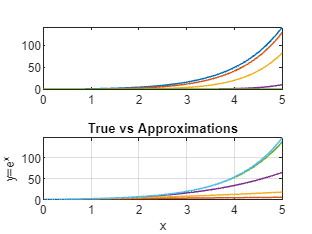


plot(x, exponential, 'LineWidth', 1);
title('True vs Approximations');
xlabel('x');
ylabel('y=e^x');
hold on;
grid on;
plot(x, approx, 'Linewidth', 1);
hold off;

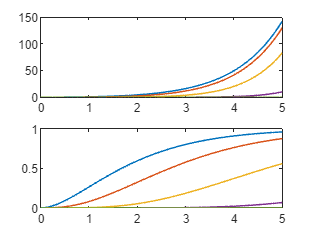

abs_error = abs(exponential - approx);
relative_error = abs_error ./ exponential;

figure;
title('Absolute error and Relative error');
ylabel('y');
xlabel('x');
xlim([0, 5]);
ylim([0, 150]);

subplot(2, 1, 1);
plot(x, abs_error, 'LineWidth', 1)
subplot(2,1,2);
plot(x, relative_error, 'LineWidth',1 )

## 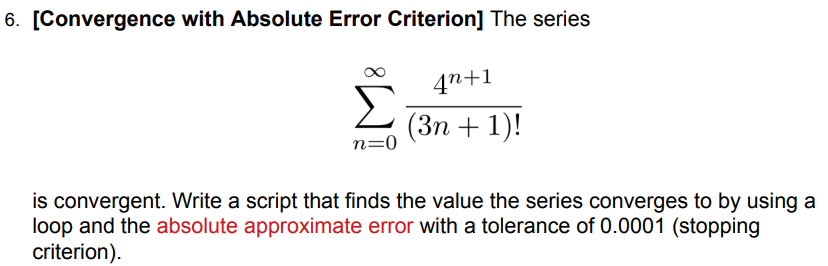

ans = [];
nida = 0;
for n = 0:9
    nida = nida + (4^(n + 1)) / factorial(3*n + 1);
    term = (4^(n + 1)) / factorial(3*n + 1);
    if (n + 1) - n
        term
end

disp(nida);

   4.679435790742804



## functions

function l = maclaurin_e(n,x)
total = 0;
for i=0:n
    total = total + (-1)^i*x.^(2*i)./factorial(2*i);
end
l=total;
end
